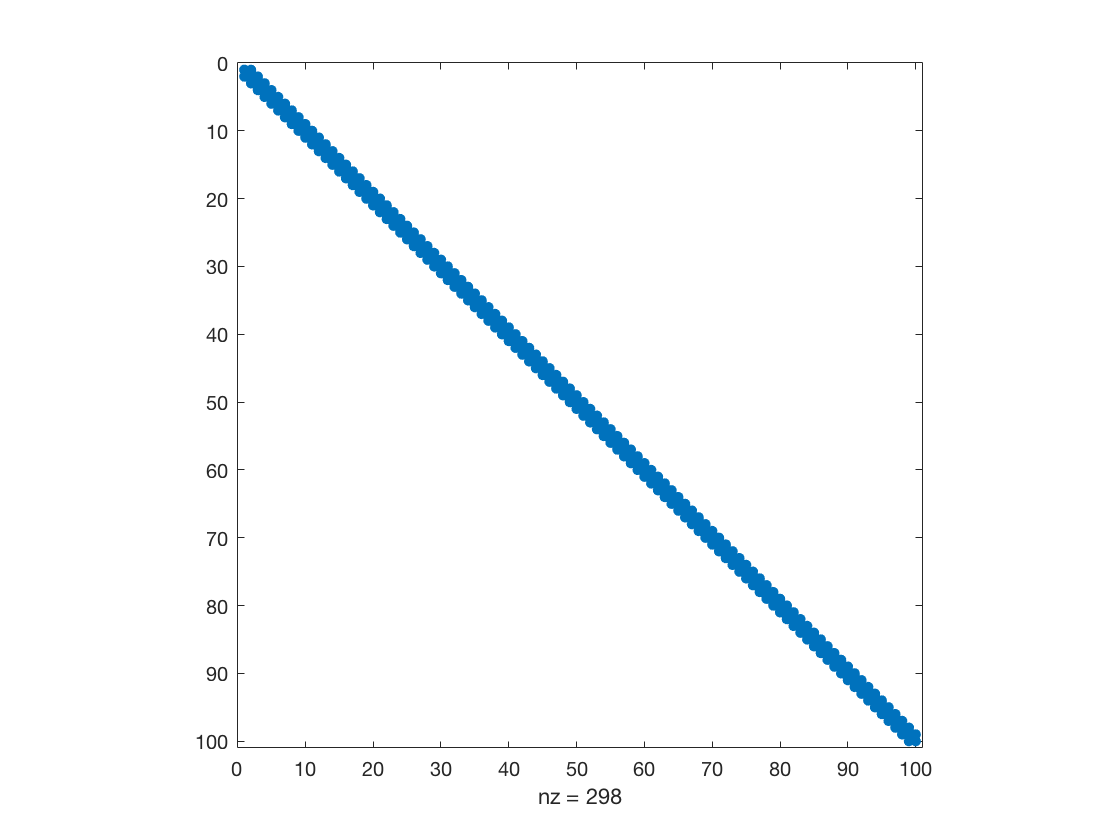

% Susan Sun: 1004016334, Gabriel Sher; Daniel Ding

clc; clear; close all;

Ul = 0;
Ur = 0;
f = 0;

%given values (from question #3)
kay = 0.005;
kappa = 1;
N = 100;
h = (1/(N+1));


%--------------------------------------------------------------------------
%QUESTION #3:
%this calls the function func_assemble to create matrix A
A = func_assemble(h, kay, kappa, N); 

%this displays the profile of A
spy(A)


%this otains the percent of non-zero entries of A
percent = 100 * nnz(A)/(N^2);
print = sprintf( 'The percent of non-zero entries of A is: %.2f %%', percent);
disp(print)

The percent of non-zero entries of A is: 2.98 %


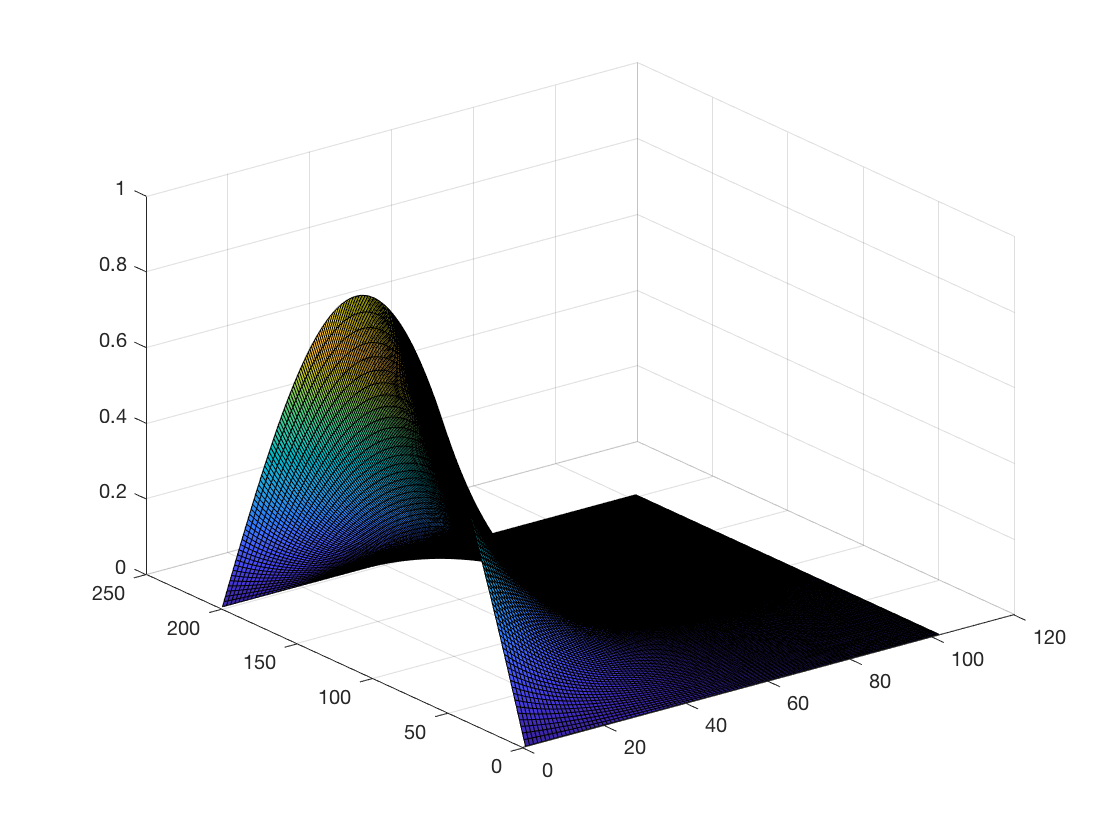


%--------------------------------------------------------------------------
%QUESTION #4

%set new params
kay = 0.005;
kappa = 1;
T = 0.5;
N = 200;
M = 100;
h = (1/(N+1));

%generate new A matrix based on updated parameters
A = func_assemble(h, kay, kappa, N);

xvec = linspace(0,1,N+2);

w = zeros(N+2,1);

for i = 1:N+2
    w(i) = sin(pi*xvec(i));
end

hist_sol = resol_heat(A, h, kay, kappa, Ul, Ur, f, w, N, T);

surf(hist_sol);

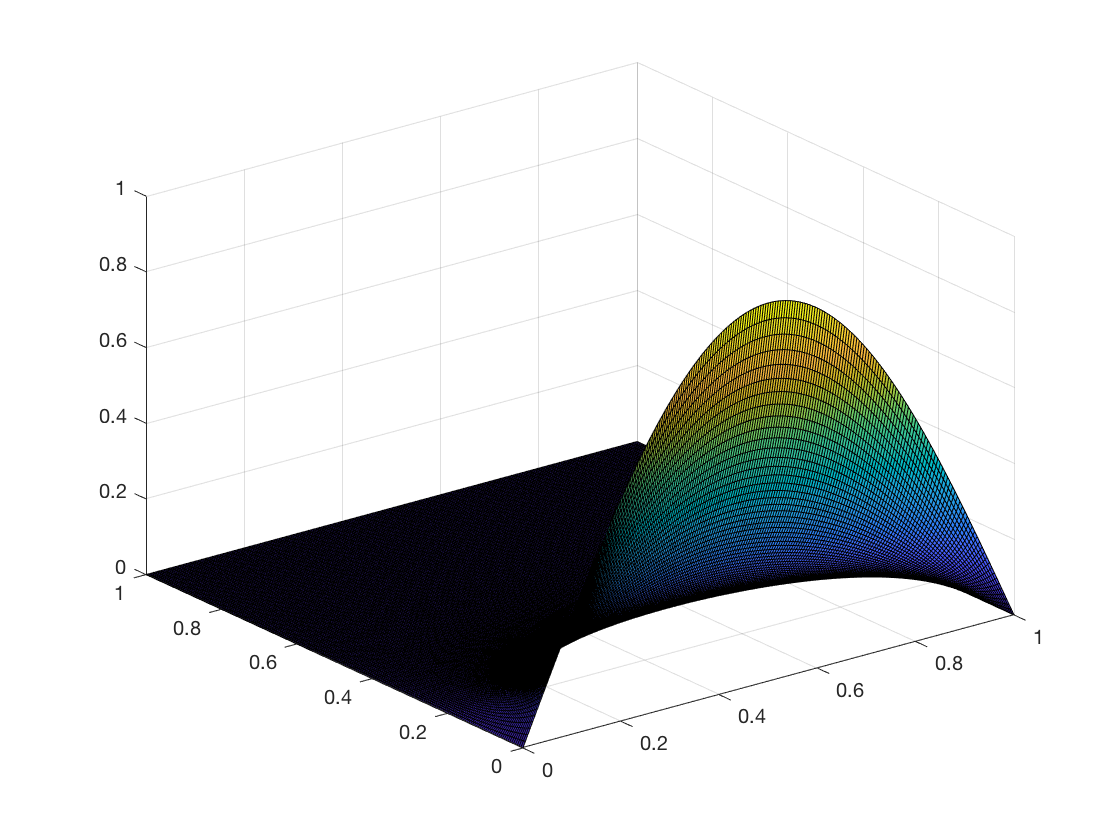


%finding the exact solution & M = 100
[X,T] = meshgrid(0:0.005:1);
Z = sin(pi.*X).*exp(-pi^2.*T);
surf(X,T,Z);

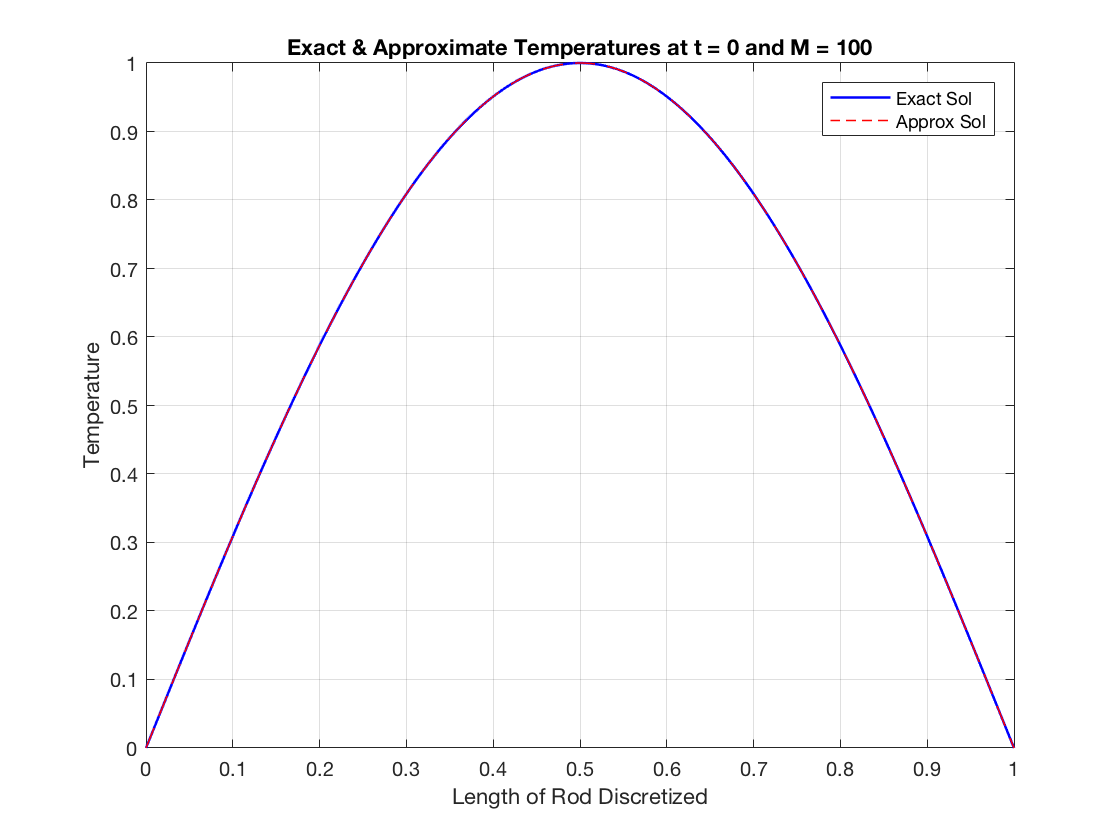


T = 0.5;
X = linspace(0,1,N+2);

Ye = sin(pi.*X).* exp(-pi^2.*0);
Ya = hist_sol(:,1);
plot(X,Ye, '-b', 'LineWidth', 1.25)
grid on
hold on
plot(X,Ya, '--r', 'LineWidth', 0.75)
legend('Exact Sol', 'Approx Sol')
title("Exact & Approximate Temperatures at t = 0 and M = 100")
xlabel("Length of Rod Discretized")
ylabel("Temperature")
hold off

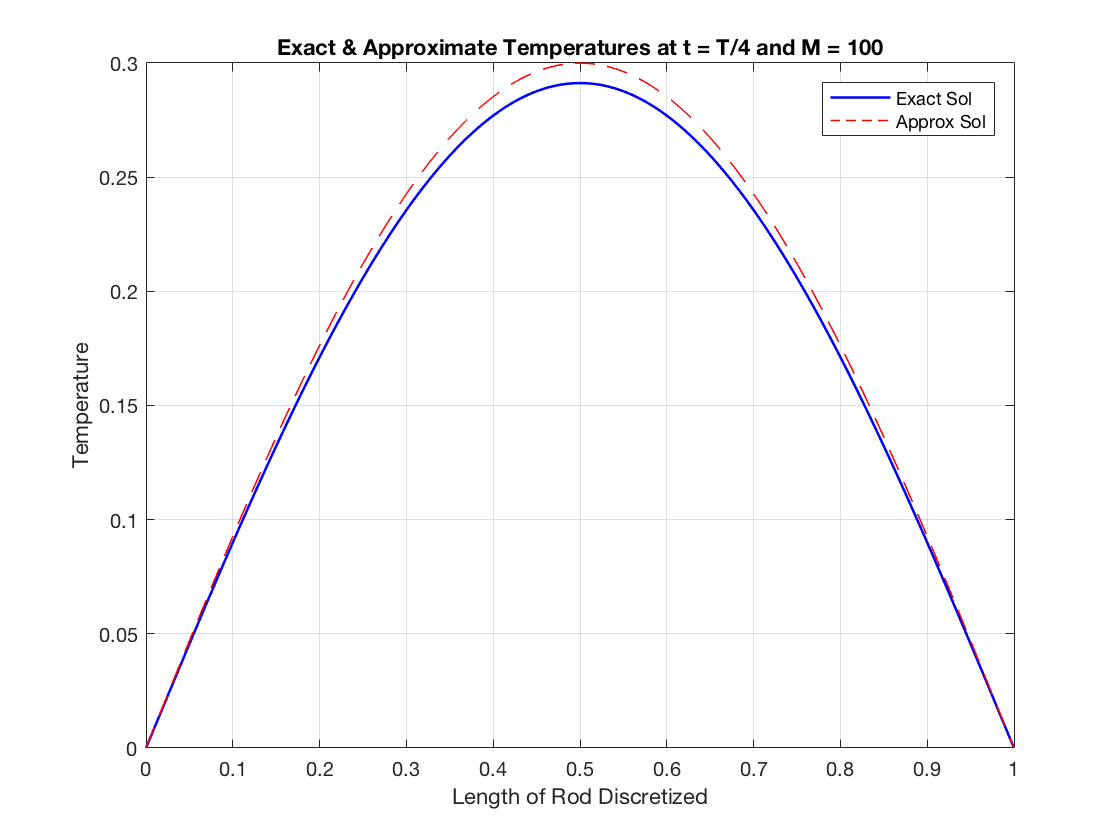


Ye = sin(pi.*X).*exp(-pi^2.*T/4);
Ya = hist_sol(:,26);
plot(X,Ye,'-b', 'LineWidth', 1.25)
grid on
hold on
plot(X,Ya, '--r', 'LineWidth', 0.75)
legend('Exact Sol', 'Approx Sol')
title("Exact & Approximate Temperatures at t = T/4 and M = 100")
xlabel("Length of Rod Discretized")
ylabel("Temperature")
hold off

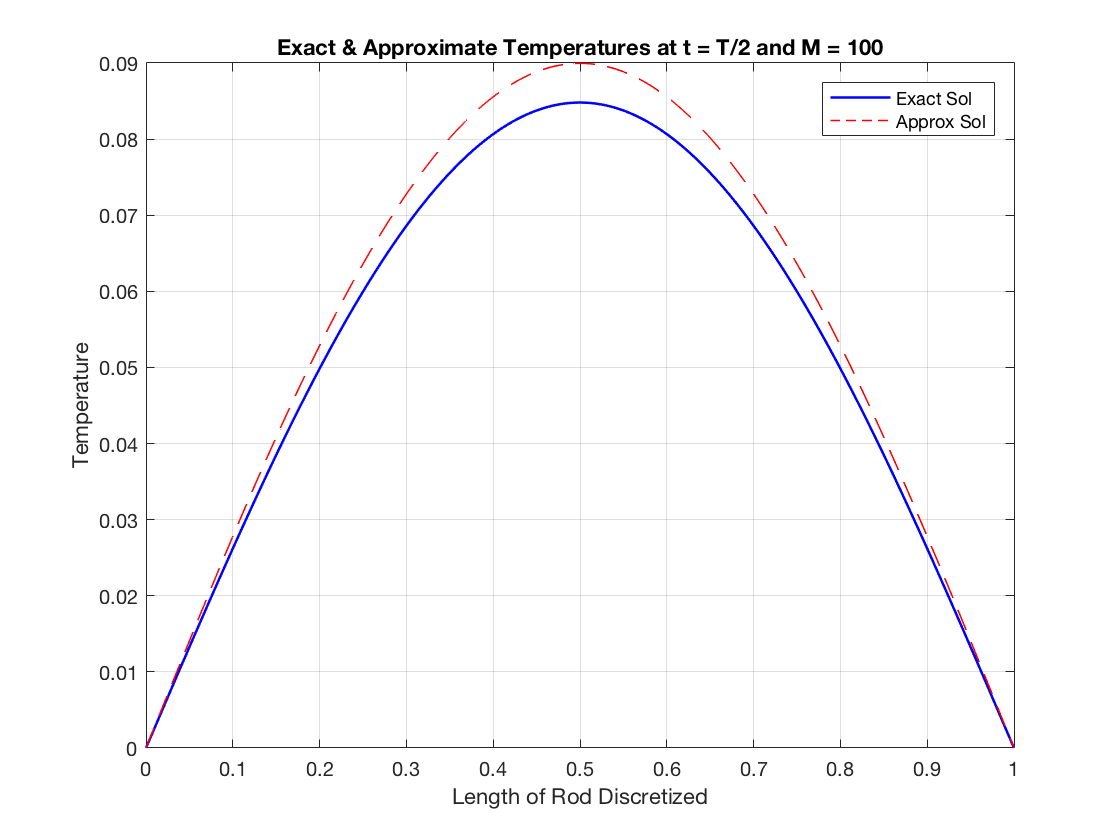


Ye = sin(pi.*X).*exp(-pi^2.*T/2);
Ya = hist_sol(:,51);
plot(X,Ye,'-b', 'LineWidth', 1.25)
grid on
hold on
plot(X,Ya, '--r', 'LineWidth', 0.75)
legend('Exact Sol', 'Approx Sol')
title("Exact & Approximate Temperatures at t = T/2 and M = 100")
xlabel("Length of Rod Discretized")
ylabel("Temperature")
hold off

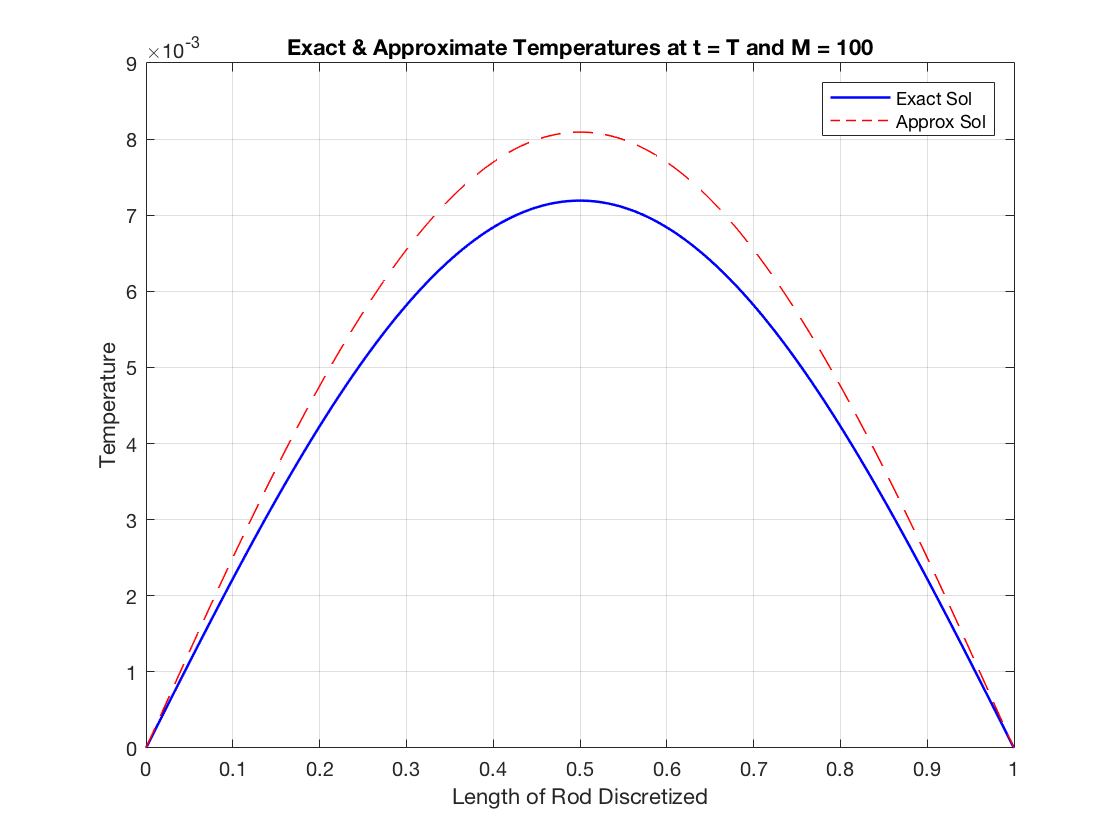


Ye = sin(pi.*X).*exp(-pi^2.*T);
Ya = hist_sol(:,101);
plot(X,Ye,'-b', 'LineWidth', 1.25)
grid on
hold on
plot(X,Ya, '--r', 'LineWidth', 0.75)
legend('Exact Sol', 'Approx Sol')
title("Exact & Approximate Temperatures at t = T and M = 100")
xlabel("Length of Rod Discretized")
ylabel("Temperature")
hold off


% if M = 1000,then k = 0.0005

T = 0.5;
N = 200;
M = 1000;
h = (1/(N+1));
kay = 0.0005;
kappa = 1;

A = func_assemble(h, kay, kappa, N);

hist_sol = resol_heat(A, h, kay, kappa, Ul, Ur, f, w, N, T);

[X,T] = meshgrid(0:0.005:1);
Z = sin(pi.*X).*exp(-pi^2.*T);
surf(X,T,Z)

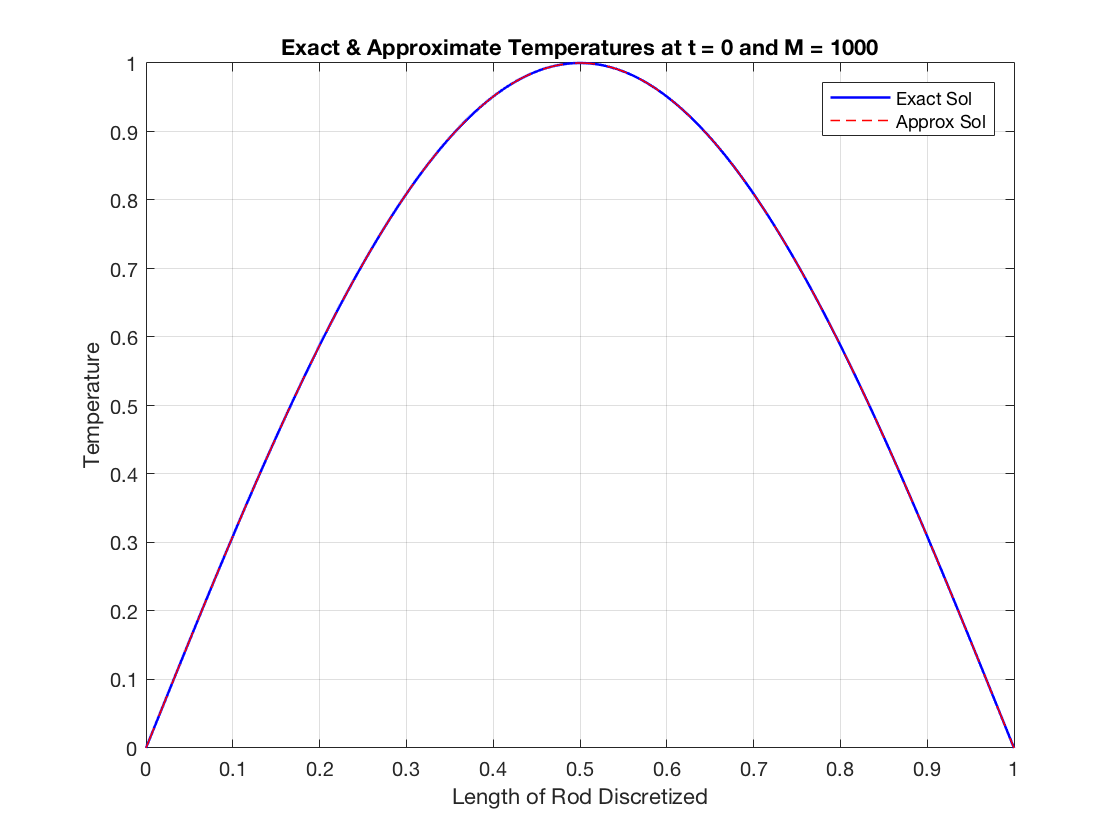


T = 0.5;
X = linspace(0,1,N+2);

Ye = sin(pi.*X).* exp(-pi^2.*0);
Ya = hist_sol(:,1);
plot(X,Ye, '-b', 'LineWidth', 1.25)
grid on
hold on
plot(X,Ya, '--r', 'LineWidth', 0.75)
legend('Exact Sol', 'Approx Sol')
title("Exact & Approximate Temperatures at t = 0 and M = 1000")
xlabel("Length of Rod Discretized")
ylabel("Temperature")
hold off

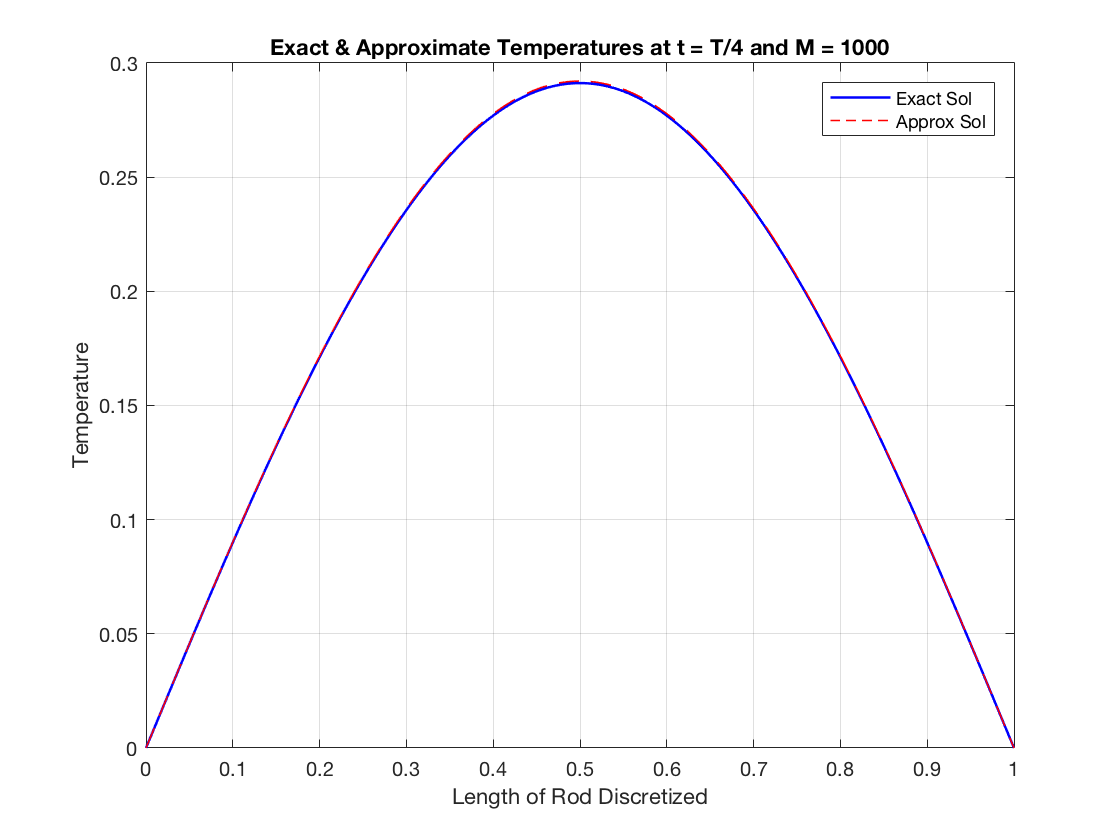


Ye = sin(pi.*X).*exp(-pi^2.*(T/4));
Ya = hist_sol(:,251);
plot(X,Ye,'-b', 'LineWidth', 1.25)
grid on
hold on
plot(X,Ya, '--r', 'LineWidth', 0.75)
legend('Exact Sol', 'Approx Sol')
title("Exact & Approximate Temperatures at t = T/4 and M = 1000")
xlabel("Length of Rod Discretized")
ylabel("Temperature")
hold off

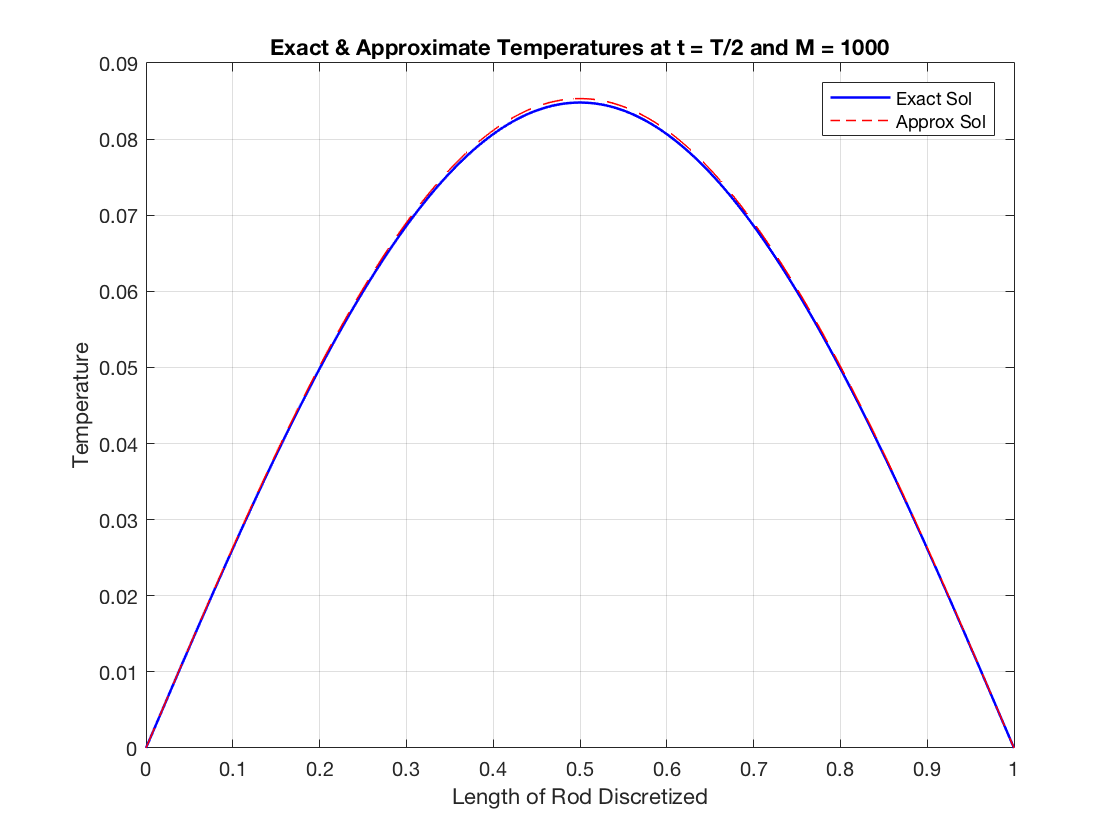


Ye = sin(pi.*X).*exp(-pi^2.*(T/2));
Ya = hist_sol(:,501);
plot(X,Ye,'-b', 'LineWidth', 1.25)
grid on
hold on
plot(X,Ya, '--r', 'LineWidth', 0.75)
legend('Exact Sol', 'Approx Sol')
title("Exact & Approximate Temperatures at t = T/2 and M = 1000")
xlabel("Length of Rod Discretized")
ylabel("Temperature")
hold off

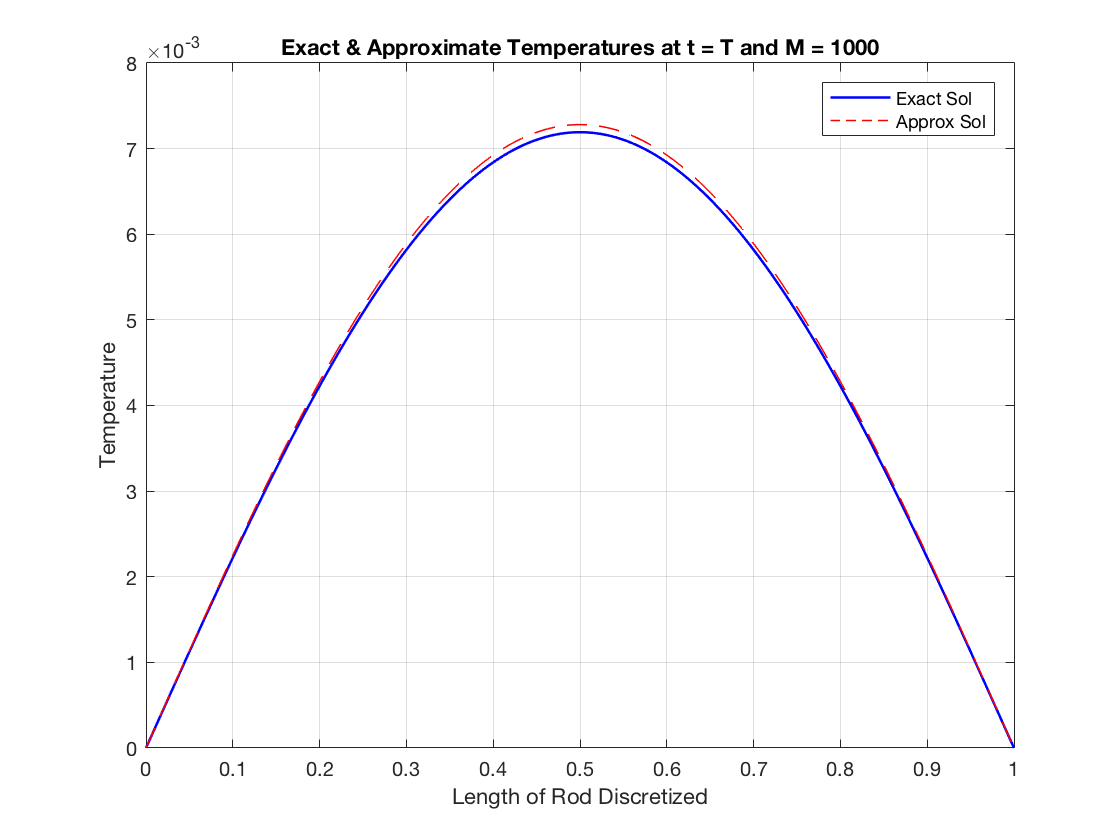


Ye = sin(pi.*X).*exp(-pi^2.*T);
Ya = hist_sol(:,1001);
plot(X,Ye,'-b', 'LineWidth', 1.25)
grid on
hold on
plot(X,Ya, '--r', 'LineWidth', 0.75)
legend('Exact Sol', 'Approx Sol')
title("Exact & Approximate Temperatures at t = T and M = 1000")
xlabel("Length of Rod Discretized")
ylabel("Temperature")
hold off

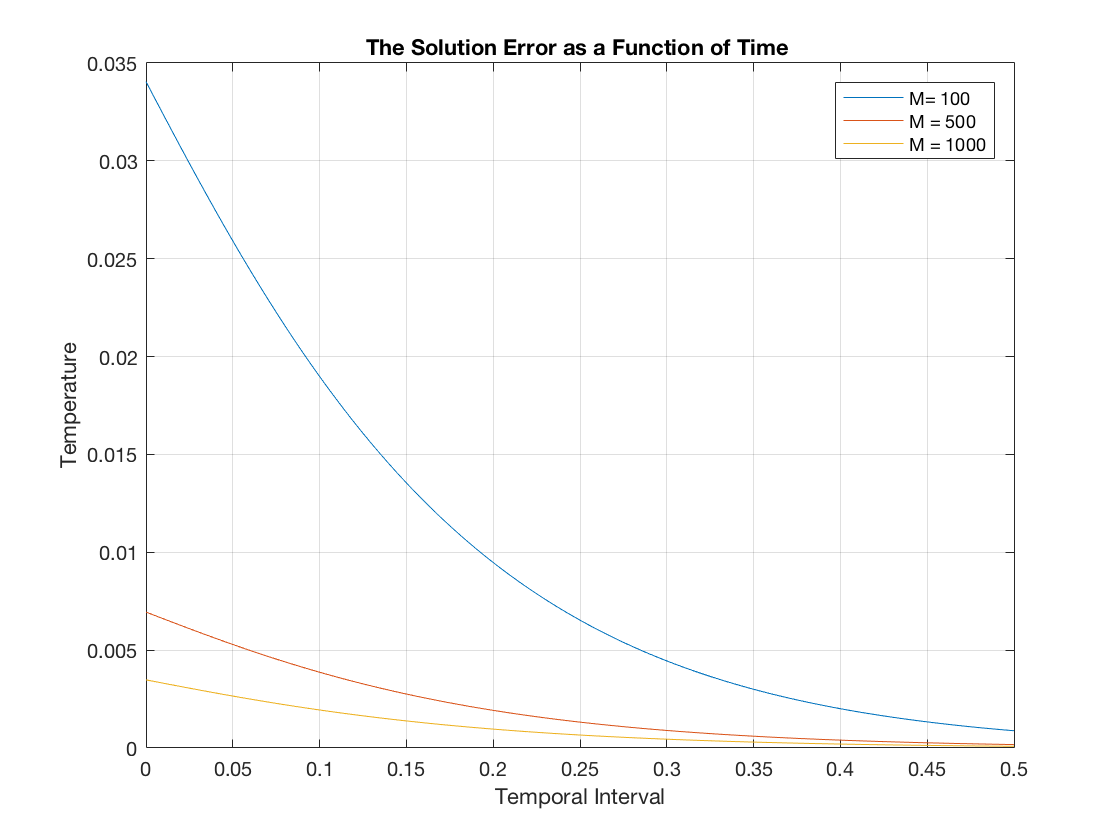

%Therefore, when you decrease the time step (incr M to 1000) the approximate
%temperature approaches the exact temperature more accurately.


%--------------------------------------------------------------------------
%QUESTION #5:

%set new params
kay = 0.005;
kappa = 1;
T = 0.5;
N = 200;
M = 100;
h = (1/(N+1));

%generate new A matrix based on updated parameters
A = func_assemble(h, kay, kappa, N);
xvec = linspace(0,1,N+2);

%generate new w vector based on updated parameters
w = zeros(N+2,1);
for i = 1:N+2
    w(i) = sin(pi*xvec(i));
end
%generate new hist_sol matrix based on updated parameters
hist_sol = resol_heat(A, h, kay, kappa, Ul, Ur, f, w, N, T);

%Exact solutions in a N+2 x M+2 matrix
exactSols = NaN(N+2,M+2);
for i = 1:1:M+2
    exactSols(:,i) = sin(pi.*X).*exp(-pi^2.*(kay*i));
end
%Generate matrix of all Approx - Exact sols squared
diffSols = (hist_sol - exactSols).*(hist_sol - exactSols);

%Sum up columns in diffSols from i = 1 to N
tempEr = zeros(1,M+1);
for i = 1:1:M+1
    tempEr(i) = sum(diffSols(2:end-2,i));
end

%multiply summation by h and squareroot
actualEr100 = sqrt(h.*tempEr);

%repeat above steps for M = 500 and M = 1000
M = 500;
kay = 0.001;
A = func_assemble(h, kay, kappa, N);
xvec = linspace(0,1,N+2);
w = zeros(N+2,1);
for i = 1:N+2
    w(i) = sin(pi*xvec(i));
end
hist_sol = resol_heat(A, h, kay, kappa, Ul, Ur, f, w, N, T);
exactSols = NaN(N+2,M+2);
for i = 1:1:M+2
    exactSols(:,i) = sin(pi.*X).*exp(-pi^2.*(kay*i));
end
diffSols = (hist_sol - exactSols).*(hist_sol - exactSols);
tempEr = zeros(1,M+1);
for i = 1:1:M+1
    tempEr(i) = sum(diffSols(2:end-2,i));
end
actualEr500 = sqrt(h.*tempEr);

M = 1000;
kay = 0.0005;
A = func_assemble(h, kay, kappa, N);
xvec = linspace(0,1,N+2);
w = zeros(N+2,1);
for i = 1:N+2
    w(i) = sin(pi*xvec(i));
end
hist_sol = resol_heat(A, h, kay, kappa, Ul, Ur, f, w, N, T);
exactSols = NaN(N+2,M+2);
for i = 1:1:M+2
    exactSols(:,i) = sin(pi.*X).*exp(-pi^2.*(kay*i));
end
diffSols = (hist_sol - exactSols).*(hist_sol - exactSols);
tempEr = zeros(1,M+1);
for i = 1:1:M+1
    tempEr(i) = sum(diffSols(2:end-2,i));
end
actualEr1000 = sqrt(h.*tempEr);

%This generates the different x axis for different time steps
x1 = 0:0.005:0.5;
x2 = 0:0.001:0.5;
x3 = 0:0.0005:0.5;

plot(x1,actualEr100);
grid on
hold on
plot(x2,actualEr500);
hold on
plot(x3,actualEr1000);
legend('M= 100', 'M = 500', 'M = 1000')
title("The Solution Error as a Function of Time ")
xlabel("Temporal Interval")
ylabel("Temperature")
hold off



%--------------------------------------------------------------------------
%QUESTION #6:

% When N = 500 & M = 1000:

kay = 0.005;
kappa = 1;
T = 0.5;
N = 200;
M = 100;
h = (1/(N+1));

%generate new A matrix based on updated parameters
tic;
A = func_assemble(h, kay, kappa, N);
hist_sol = resol_heat(A, h, kay, kappa, Ul, Ur, f, w, N, T);
toc

Elapsed time is 0.185239 seconds.


%without sparse, the elapsed time was 0.185s

tic;
A = func_assemble(h, kay, kappa, N);
A = sparse(A);
hist_sol = resol_heat(A, h, kay, kappa, Ul, Ur, f, w, N, T);
toc

Elapsed time is 0.081598 seconds.


%with sparse, the elapsed time was 0.0816s

%Thereforse, sparse decreases the calculation time by 56%.

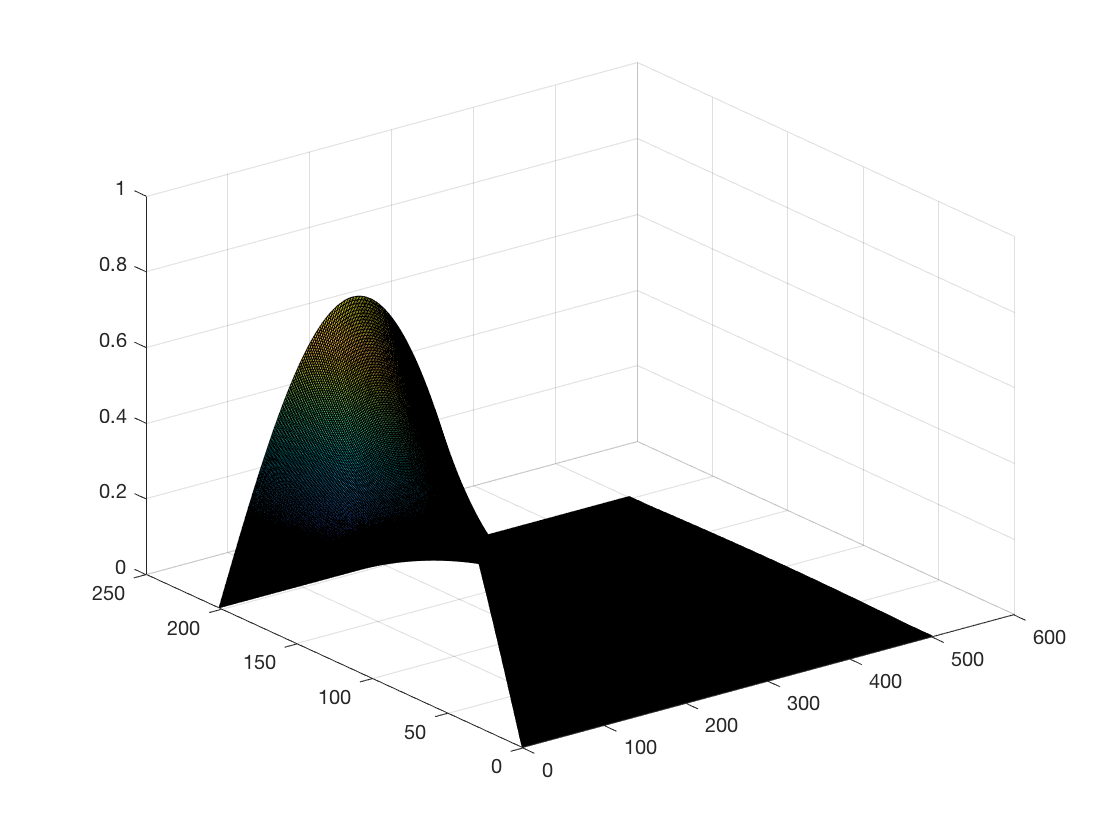


%--------------------------------------------------------------------------
%QUESTION #7:

%set new params

kappa = 1;
T = 0.5;
N = 200;
M = 500;
h = (1/(N+1));
kay = T/M;

%generate new A matrix based on updated parameters

A = func_assemble(h, kay, kappa, N);
A = sparse(A);

xvec = linspace(0,1,N+2);

w = zeros(N+2,1);

for i = 1:N+2
    w(i) = sin(pi*xvec(i));
end

hist_sol = resol_heat(A, h, kay, kappa, Ul, Ur, f, w, N, T);

surf(hist_sol);

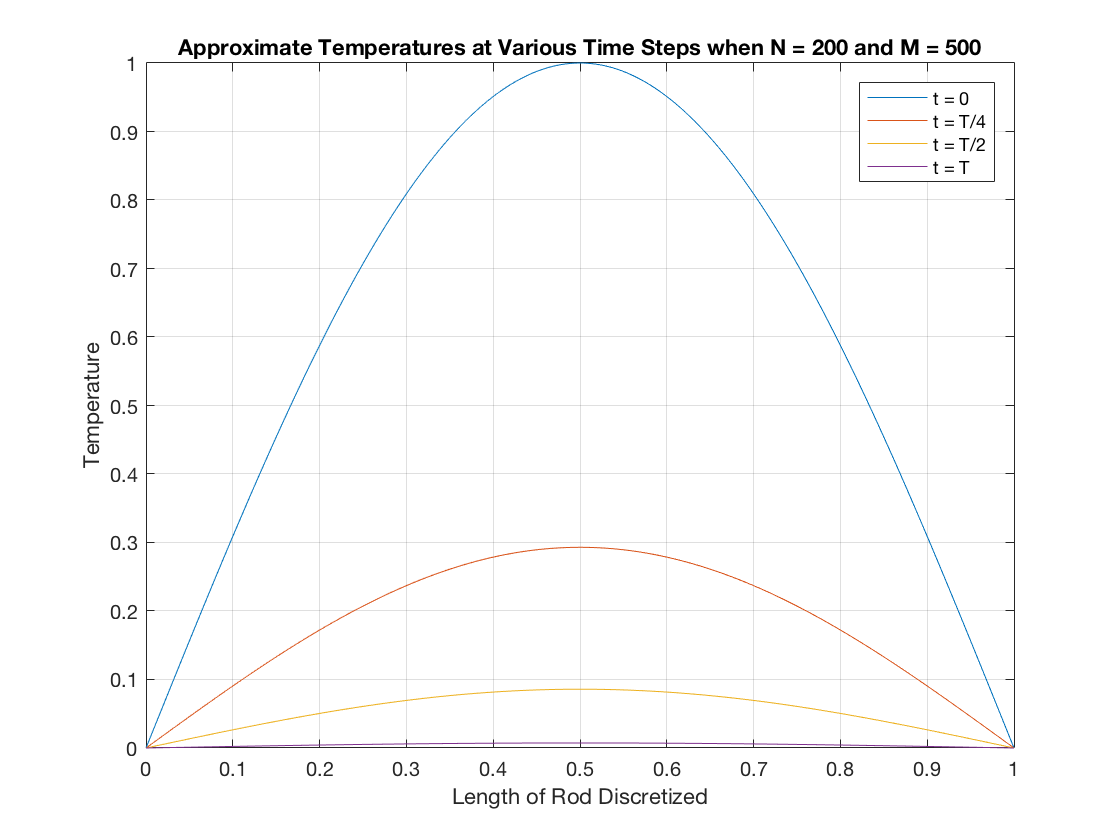


%finding the approx solutions when N = 200 M = 500
[X,T] = meshgrid(0:0.005:1);

T = 0.5;
X = linspace(0,1,N+2);

Ya1 = hist_sol(:,1);
Ya2 = hist_sol(:,126);
Ya3 = hist_sol(:,251);
Ya4 = hist_sol(:,501);

plot(X,Ya1)
grid on
hold on
plot(X,Ya2)
hold on
plot(X,Ya3)
hold on
plot(X,Ya4)
legend('t = 0', 't = T/4','t = T/2', 't = T')
title("Approximate Temperatures at Various Time Steps when N = 200 and M = 500")
xlabel("Length of Rod Discretized")
ylabel("Temperature")
hold off

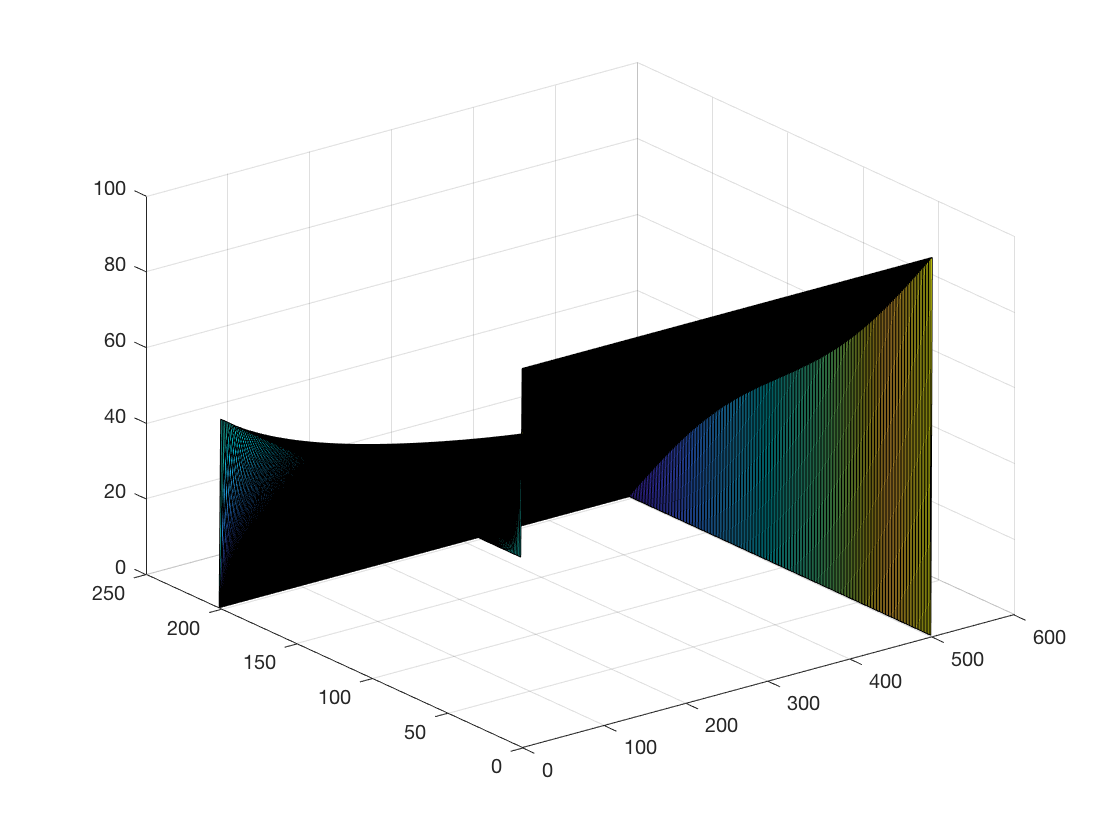


%--------------------------------------------------------------------------
%QUESTION #8:

%set new params
Ul = 100;
Ur = 0;
f = 0;
kappa = 0.1;
T = 0.5;
N = 200;
M = 500;
h = (1/(N+1));
kay = T/M;

%generate new A matrix based on updated parameters
A = func_assemble(h, kay, kappa, N);
A = sparse(A);

xvec = linspace(0,1,N+2);

w = zeros(N+2,1);

for i = 1:N+2
    w(i) = 50;
end

hist_sol = resol_heat(A, h, kay, kappa, Ul, Ur, f, w, N, T);

surf(hist_sol);

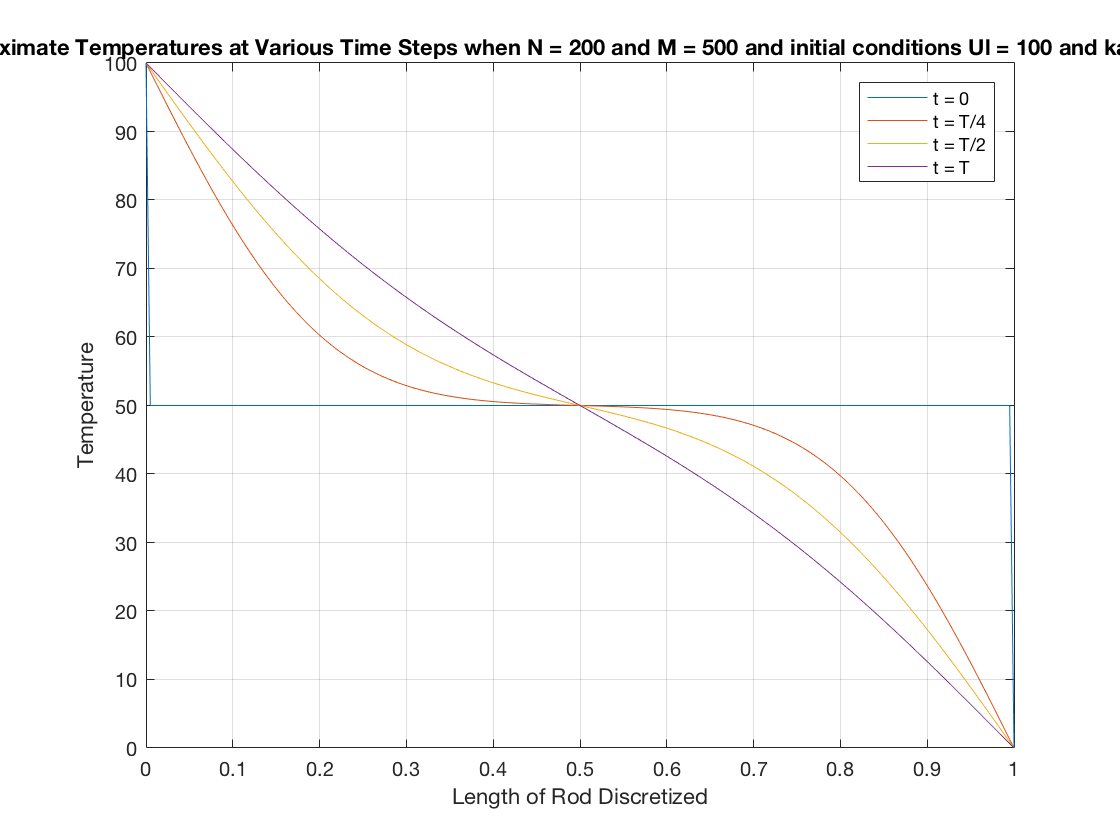


%finding the approx solutions when N = 200 M = 500
[X,T] = meshgrid(0:0.005:1);

T = 0.5;
X = linspace(0,1,N+2);

Ya1 = hist_sol(:,1);
Ya2 = hist_sol(:,126);
Ya3 = hist_sol(:,251);
Ya4 = hist_sol(:,501);

plot(X,Ya1)
grid on
hold on
plot(X,Ya2)
hold on
plot(X,Ya3)
hold on
plot(X,Ya4)
legend('t = 0', 't = T/4','t = T/2', 't = T')
title("Approximate Temperatures at Various Time Steps when N = 200 and M = 500 and initial conditions Ul = 100 and kappa = 0.1")
xlabel("Length of Rod Discretized")
ylabel("Temperature")
hold off

function [A] = func_assemble(h, kay, kappa, N)
    %creates a vector of length N with zeros as the elements
    v1 = zeros(1,N);
    %creates a vector of length N-1 with zeros as the elements
    v2 = zeros(1,(N-1));
    
for i = 1:1:N  
    %this populates the vector of length N with the same value
    v1(i) = ((1/kay) + (2 * kappa/(h*h))); 
end 

for i = 1:1:N-1
    %this populates the vector of length N-1 with the same value
    v2(i) = (-kappa/h^2);
end
    %this creates a matrix of N by N dimentions with 
    %vector v1 as the main diagnonal and v2 as oth the first {super,sub}diagonal.
    A = diag(v1) + diag(v2,1) + diag(v2,-1);
    
end  


function [hist_sol] = resol_heat(A, h, kay, kappa, Ul, Ur, f, w, N, T)
    
    % technically M = (T/kay) - 1 
    % but the question demands M = 100 COME BACK TO THIS!!!!
    % change this as required 
    M = T/kay;

    %generating history matrix with boundary values n+2, m+2
    hist_sol = zeros(N+2,M+2);
    
    %settings boundaries
    hist_sol(1,:) = Ul;
    hist_sol(N+2,:) = Ur;
    
    w(1) = Ul;
    w(N+2) = Ur; 
    
    for i = 1:1:N+2

        hist_sol(i,1) = w(i);
        
    end 
    
    %form the B vector 
    finalvector = zeros(N,1);
    finalvector(1) = Ul;
    finalvector(N) = Ur;
    
    %temp hist_sol with small dimensions
    temp = zeros(N,M);
    
    %store the first column in a prev vector 
    for i = 2:1:N+1
        prevColumn(i-1,1) = w(i);
    end 
    
    %operate
    for i = 1:1:M
        
        B = (1/kay).*prevColumn + (kappa/h^2).*finalvector;
           
        result = A\B;
        temp(:,i) = result;
        prevColumn = temp(:,i);
    end 
    
    temp;
    
    hist_sol(2:N+1,2:M+1) = temp;
                    
    
end
